# Demo 01 : Phantom data

The phantom data is acquired using stack-of-spiral GRE sequence at Siemens 3T Prisma(16 channel) for quick testing. Precalculated Coil maps from reference data by bart and registered fieldmaps [in rad/s] from a seperate multi-echo GRE scan are provided. Make sure you have SpiralReco(including subfolders) and [mapVBVD](https://github.com/pehses/mapVBVD.git) for reading Siemens rawdata is in path. Large 9 T test dataset can be obtianed from [zenodo.org](https://zenodo.org/doi/10.5281/zenodo.8356994).

set up data and a function handle for plotting!

%addpath(genpath('SpiralReco_folder'))
cd(fileparts(which('demo01_phantomdata.mlx')));
twix=mapVBVD('testdata/meas_MID00117_FID07732_peSpiral_3D_R3_1p5iso_long.dat');

Software version: VD (!?)
Scan 1/2, read all mdhs:
    100 % read in    0 s; estimated time left:    0 s 
          parse mdhs... done. (0.0101879 seconds)
Scan 2/2, read all mdhs:
    100 % read in    0 s; estimated time left:    0 s 
          parse mdhs... done. (0.0090921 seconds)


load('testdata/csm_fm.mat');
myimagesc= @(imxx) imagesc([],[],flip(squeeze(abs(imxx(1,:,:,8))),1));

## Perform gridding reconstruction

Now we perform simple gridding reconstruction with GIRF correction, density compenation and sum of squares coil combination. The data is 3 fold undersampled. 

r_alias=SpiralReco(twix,'doCoilCombine','sos');

slice =  1/ 1 | Rep =  1/ 1 | time =    3.7 s


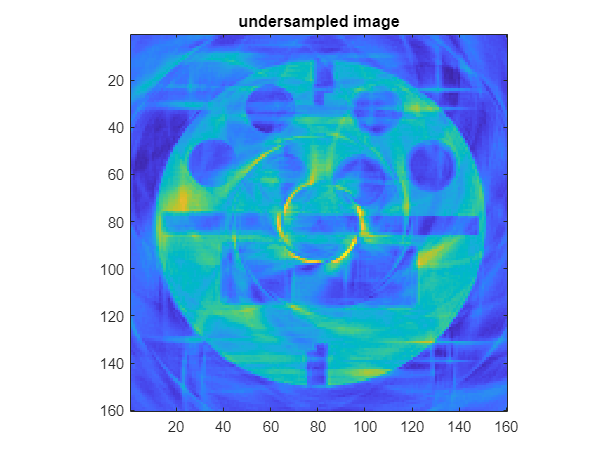

figure,myimagesc(r_alias.img),title('undersampled image'),axis image

## SPIRIT reconstruction

If we don't have explicit coil sensitivities, we can perform SPIRIT reconstruciton. For more speed and less memory requirements, Let's enable SVD coil compression to preserve 90% variance. We turn off the density pre-conditioning and increase iterations for better convergenece. SPIRIT reconstruciton is not throughly tested. 

r_spirit=SpiralReco(twix, 'doCoilCombine','sos',....
    'doCoilCompression',0.90,'doDCF','none', ...
     'doPAT','SPIRIT','maxit',100);

Compressing 16 coils into 7 coils with 90% signal energy
note in nufft: could save flops via smarter padded FFT
slice =  1/ 1 | Rep =  1/ 1 | time =  107.8 s


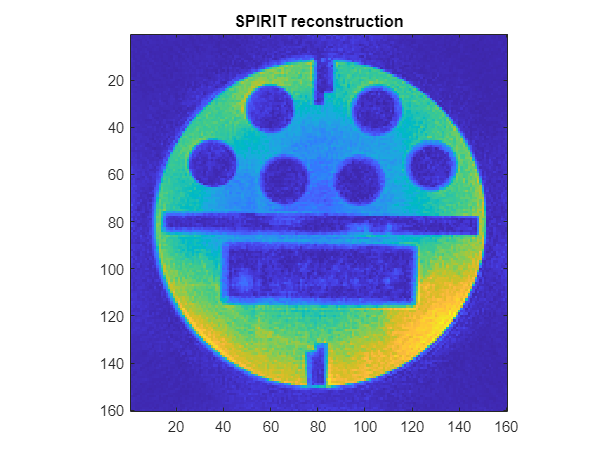

figure,myimagesc(r_spirit.img),title('SPIRIT reconstruction'),axis image

## Perform preconditioned CG-SENSE

As we have coil senstivies from BART(loaded with the data), we can do a much faster density preconditioned CG-SENSE reconstruction. Try different/no density compensation by using 'doDCF' options: 'none', 'Jackson','Voronoi'. 

r_cg=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',20);

slice =  1/ 1 | Rep =  1/ 1 | time =   34.8 s


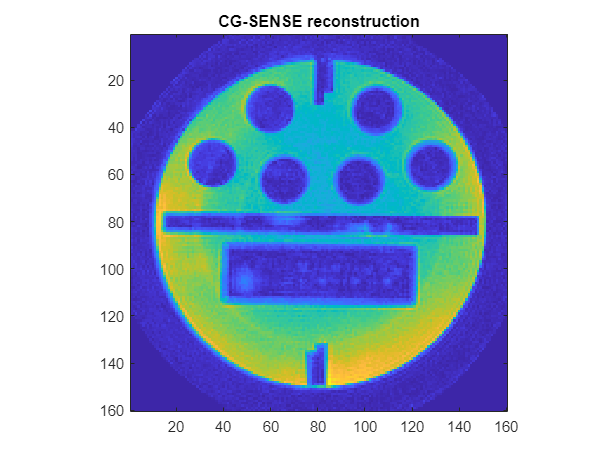

figure,myimagesc(r_cg.img),title('CG-SENSE reconstruction'),axis image

## B0 correction

The spatial B0 can be added to the signal model through time or frequency segmentation methods. In the current implementation, frequency segmentation needs more memory for calculating the interpolation weights (and hence, not recommended for 3D).

r_cgMTI=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',20, ...
    'doB0Corr','MTI','fm',fm2);

slice =  1/ 1 | Rep =  1/ 1 | time =  127.4 s


r_cgMFI=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',20, ...
    'doB0Corr','MFI','fm',fm2);

slice =  1/ 1 | Rep =  1/ 1 | time =  131.9 s


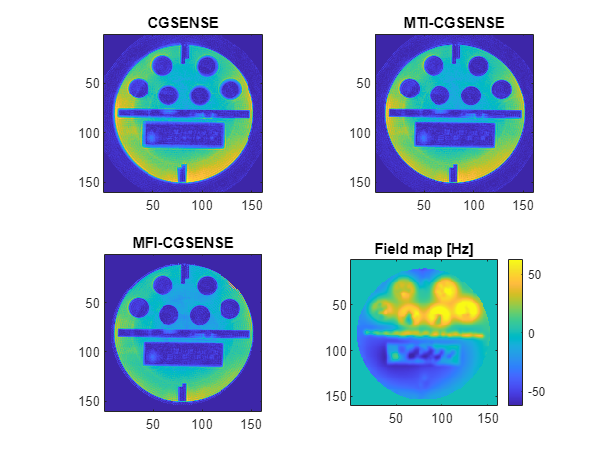

figure,
subplot(221),myimagesc(r_cg.img),title('CGSENSE'),axis image
subplot(222),myimagesc(r_cgMTI.img),title('MTI-CGSENSE'),axis image
subplot(223),myimagesc(r_cgMFI.img),title('MFI-CGSENSE'),axis image
subplot(224),imagesc(flip(fm2(:,:,8)./(2*pi),1)),title('Field map [Hz]'),axis image,colorbar

## GPU reconstruction

SpiralReco toolbox can also intergrate well with the [gpuNUFFT](https://github.com/andyschwarzl/gpuNUFFT.git) toolbox. You can pick NUFFT computation mode with 'CompMode' : 'CPU3D', 'GPU3D' and 'CPU2DHybrid'(default). It is CPU2Dhybrid NUFFT because the slice direction is an FFT for faster and less memory intensive reconstruction. For 'GPU3D', the [gpuNUFFT](https://github.com/andyschwarzl/gpuNUFFT.git) toolbox should be in path.

r_cgMTI_gpu=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',20, ...
    'doB0Corr','MTI','fm',fm2,...
'CompMode','GPU3D');

slice =  1/ 1 | Rep =  1/ 1 | time =   55.5 s


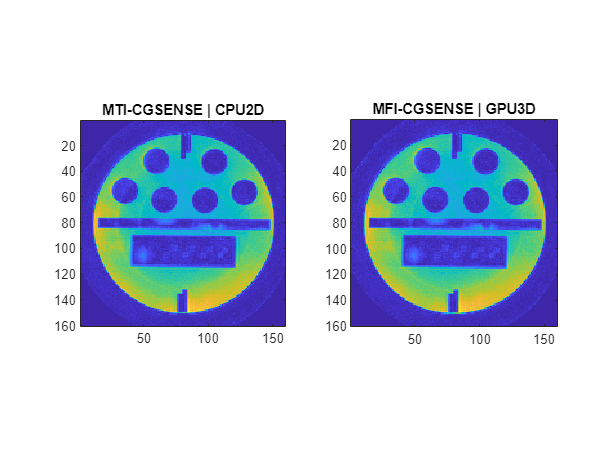

figure,
subplot(121),myimagesc(r_cgMTI.img),title('MTI-CGSENSE | CPU2D'),axis image
subplot(122),myimagesc(r_cgMTI_gpu.img),title('MFI-CGSENSE | GPU3D'),axis image

## Regularization

Noise amplifications with CG iterations due to poor conditioning can be controlled with Tikhonov/L2 regularization.  

 r_cg=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',100);

slice =  1/ 1 | Rep =  1/ 1 | time =  150.9 s


r_cg_reg=SpiralReco(twix,'csm',csm,'doPAT','CGSENSE','doDCF','Jackson','maxit',100, ...
    'reg','Tikhonov','reg_lambda',0.1);

slice =  1/ 1 | Rep =  1/ 1 | time =  124.4 s


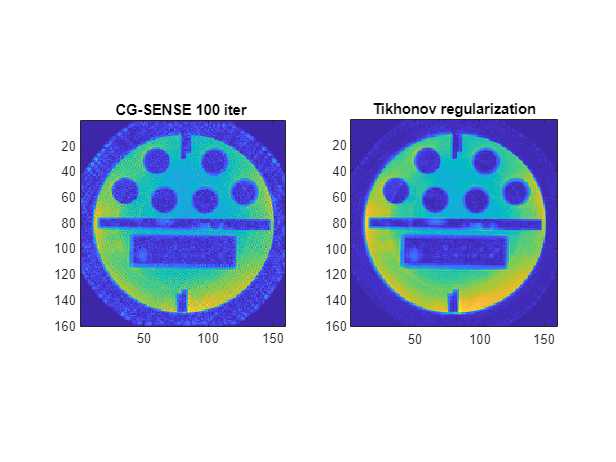


figure,
subplot(121),myimagesc(r_cg.img),title('CG-SENSE 100 iter '),axis image
subplot(122),myimagesc(r_cg_reg.img),title('Tikhonov regularization'),axis image

## Bring in your own data

Figure out the following for your own data.

resolution=1.25e-3; %[m] isotropic
kTraj= r_cg.KTraj; %[rad/m]
imSize=[160 160 16];
st=struct('FOV',200,'Resolution',1.25,'Ninterleaves',3); %distance in [mm] 
% noise decorrelated spiral data
sig=permute(r_alias.twix.image{''},[2 1 3 4]); %coil first
sig=reshape(r_cg.D*sig(:,:),size(sig)) ; %noise decorr 
sig=permute(sig,[2 3 4 1]); %permute [RO x PE1 xPE2 x Coils]
sig=sig(:,1:3:end,:,:); % remove zerofilling

csm_CoilLast=permute(csm,[2 3 4 1]); % [ imSize x Coils] only for CG-SENSE
fm=fm2; %[rad/s] optional can be []
adcTime=r_alias.time*1e-6; %[s] optional can be []

Calculate density compensation if you want

% only 2D possible atm
 DCF=jacksonDCF2(squeeze(complex(kTraj(1,:,:,1),kTraj(2,:,:,1))),st);
%  DCF=VoronoiDCF2D(squeeze(complex(kTraj(1,:,:,1),kTraj(2,:,:,1))));
 DCF3D=repmat(DCF,[1 1 imSize(3)]);
%no density
%    DCF3D=ones(size(DCF3D));

Construct NUFFT object with or without field map. 

 kmax=pi/resolution; % [rad/m] 
 NUFFT_obj= StackofSpirals(kTraj./(2*kmax),DCF3D,imSize,csm_CoilLast,...
                                 'CompMode','CPU2DHybrid','precision','single');

% NUFFT_obj=StackofSpiralsB0(kTraj./(2*kmax),DCF3D,imSize,csm_CoilLast,fm,adcTime(:),...
%                      'CompMode','CPU2DHybrid','precision','single',...
%                      'Method','MTI');  

Do off-center correction and density pre-compensation

%density precompensation
 sig_dcf= sig.*sqrt(DCF3D);
offcenter_PRS=[  13.9179e-3; -2.3322e-3;0]; %[m]
 offcenter_mod=squeeze(exp(1i*sum(kTraj.*offcenter_PRS(:),1)));
 sig_dcf_centered= sig_dcf.*offcenter_mod;

With the magic of operator overloading, perform density-compensated adjoint reconstruction of the undersampled data.

im_alias=NUFFT_obj'*sig_dcf_centered;

Perform cg-SENSE with LSQR if you have coils sensitivity

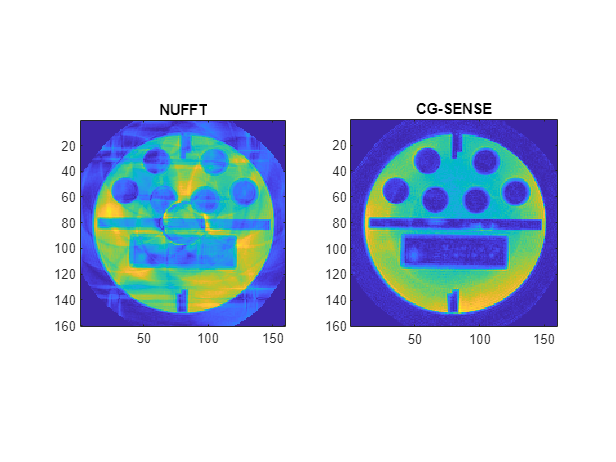

 [im_cg,flag,relres,iter,resvec]=spiralCGSENSE(NUFFT_obj,sig_dcf_centered,...
     'maxit',20,'tol',1e-5,'reg','none');
 figure,
 subplot(121),imagesc(flip(abs(im_alias(:,:,8)),1)),title('NUFFT'),axis image
 subplot(122),imagesc(flip(abs(im_cg(:,:,8)),1)),title('CG-SENSE'),axis image